%% Test of Time
tic
DisparityMap('tsukubaL.pgm','tsukubaR.pgm',3);
toc

时间已过 2.555152 秒。


## Test left to right and right to left

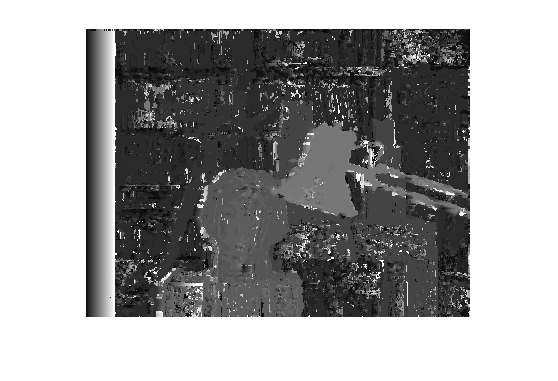

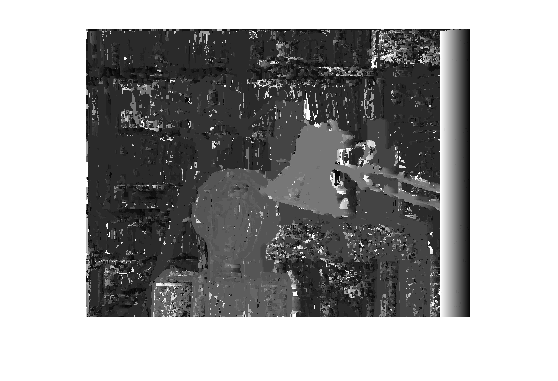

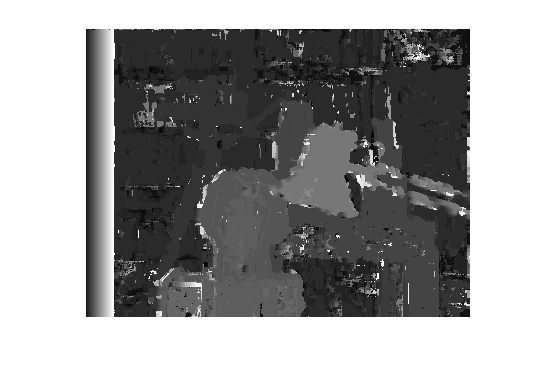

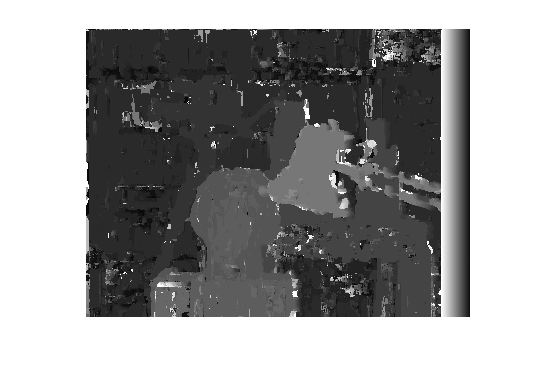

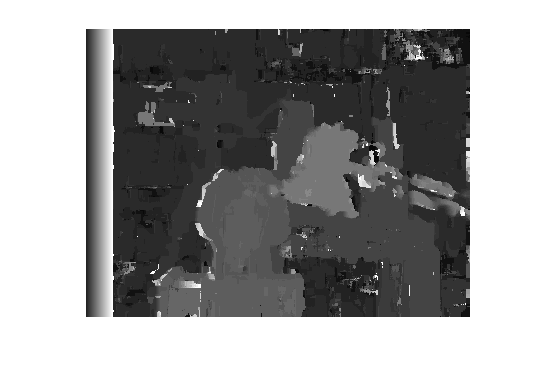

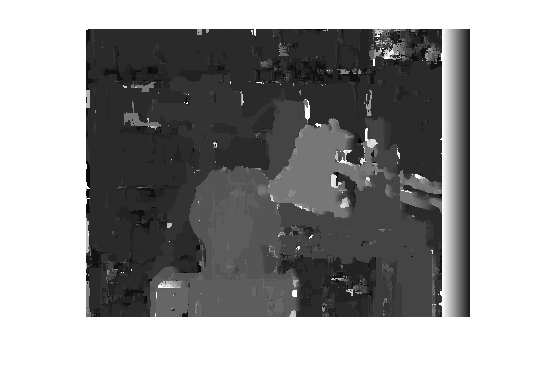


pathLeft = 'tsukubaL.pgm';
pathRight = 'tsukubaR.pgm';
looplength = 3; 
        
value = zeros(looplength,1);

for i = 1:looplength
    DispLR = DisparityMap(pathLeft,pathRight,2*i+1);
    DispRL = DisparityMap(pathLeft,pathRight,2*i+1,false);
    
    temp1 = DispLR(:,31:end-30);
    temp2 = DispRL(:,31:end-30);
    temp = (temp1-temp2).^2;
    value(i) = sum(sum(temp));
end


[minValue, index] = min(value)

minValue = 1651482

index = 3